## Fourier transformation

clear all;
close all;
clc;

syms tc xc omega

xc = 1 - abs(tc)

$$xc = 1-\left|\mathrm{tc}\right|$$

Xc = int( xc*exp(-1j*omega*tc), 'tc', -1, 1)

$$Xc = \frac{2}{\omega^{2}}-\frac{{\mathrm{e}}^{-\omega \,\mathrm{i}}\,\left(1+\omega \,\mathrm{i}\right)}{\omega^{2}}+\frac{{\mathrm{e}}^{\omega \,\mathrm{i}}\,\left(-1+\omega \,\mathrm{i}\right)}{\omega^{2}}-\frac{\sqrt{2}\,\left(\frac{{\mathrm{e}}^{-\omega \,\mathrm{i}}}{2}-\frac{{\mathrm{e}}^{\omega \,\mathrm{i}}}{2}\right)}{\sqrt{\omega \,\mathrm{i}}\,\sqrt{\frac{\omega \,\mathrm{i}}{2}}}$$

## Fast Fourier Transformation

nt = 1000;
td = linspace(-1,1,nt);

xd = 1 - abs(td);

% Sampling period
T = td(2)-td(1);

% Sampling frequency
Fs = 1/T;

% Fast Fourier Transformation of the signal
omegad = 2*pi*Fs/nt*(-nt/2:nt/2-1)

omegad = 1.0e+03 *

   -1.5692   -1.5661   -1.5629   -1.5598   -1.5567   -1.5535   -1.5504   -1.5473   -1.5441   -1.5410   -1.5378   -1.5347   -1.5316   -1.5284   -1.5253   -1.5221   -1.5190   -1.5159   -1.5127   -1.5096   -1.5065   -1.5033   -1.5002   -1.4970   -1.4939   -1.4908   -1.4876   -1.4845   -1.4813   -1.4782   -1.4751   -1.4719   -1.4688   -1.4657   -1.4625   -1.4594   -1.4562   -1.4531   -1.4500   -1.4468   -1.4437   -1.4405   -1.4374   -1.4343   -1.4311   -1.4280   -1.4249   -1.4217   -1.4186   -1.4154


Xd = abs(fftshift(2*fft(xd)/nt));




## Visualisation

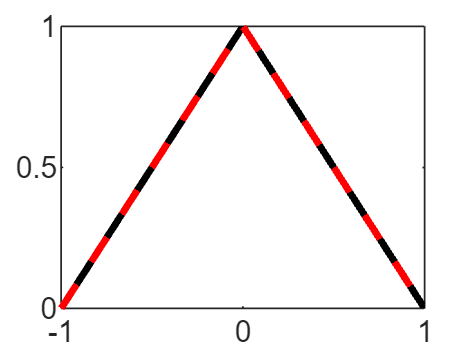

% signals
figure
fplot(xc,[-1,1],'k-',LineWidth=2)
hold on
plot(td,xd,'r--',LineWidth=2)

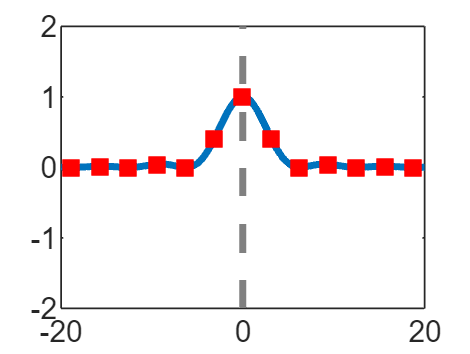


% spectra
figure
fplot(abs(Xc),[-20,20],LineWidth=2)
hold on
plot(omegad,Xd,'rs',MarkerFaceColor='r')
ylim([-0.2,1.2])
xlim([-20,20])

xlabel('\omega [rad/s]')
ylabel('|A| [signal unit]')